Hugh Transform

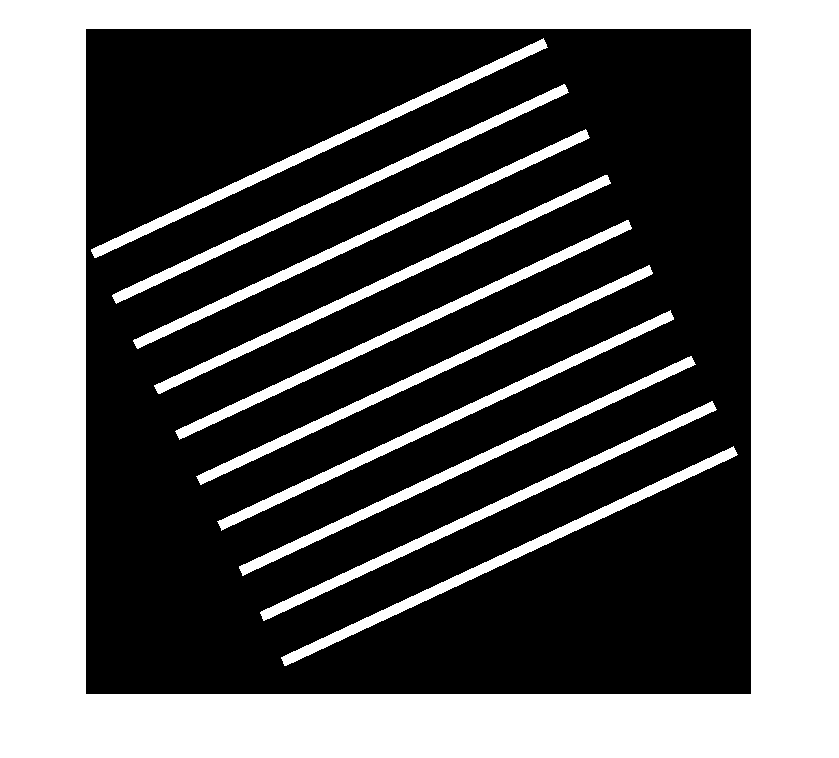

clear
Image1a = imread('Image1a.tif');
imshow(Image1a)

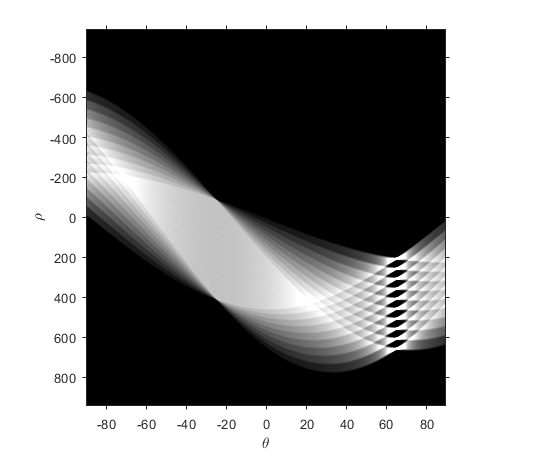


[H, teta, ro] = hough(Image1a, 'Rhoresolution', 5, 'Theta', -90:0.5:89.5);
H1 = imadjust(rescale(H));
imshow(H1,'XData',teta,'YData',ro);
xlabel('\theta'), ylabel('\rho');
axis on, axis normal, hold on;

[r,t] = find(H==max(H(:)));
tetaAngle= 90 - teta(t(1))

tetaAngle = 25

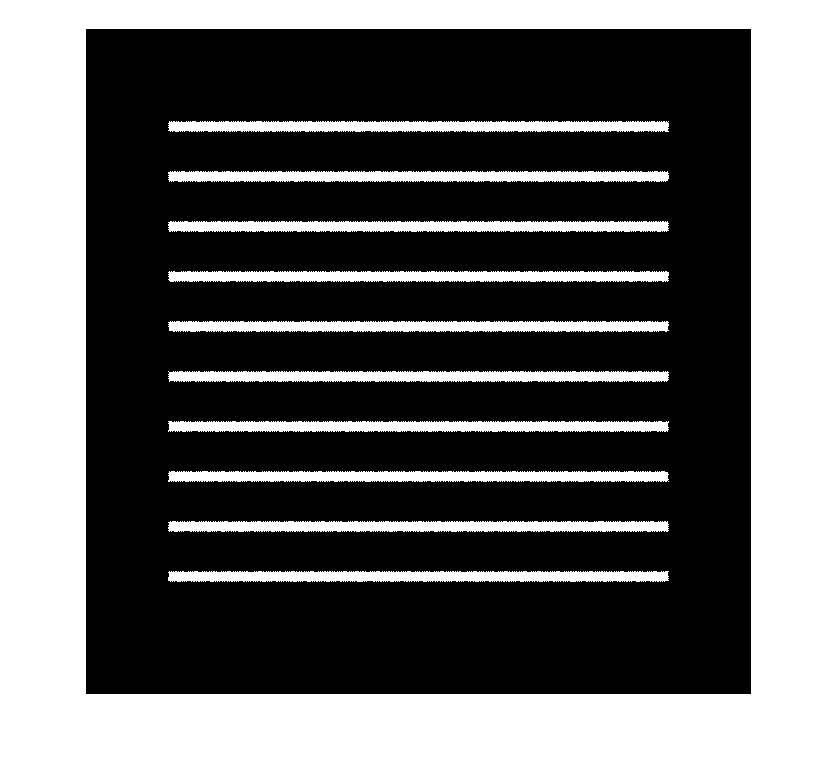

image1a_rotated = imrotate(Image1a,-tetaAngle,'bicubic','crop');
clf
figure(2)
imshow(image1a_rotated)

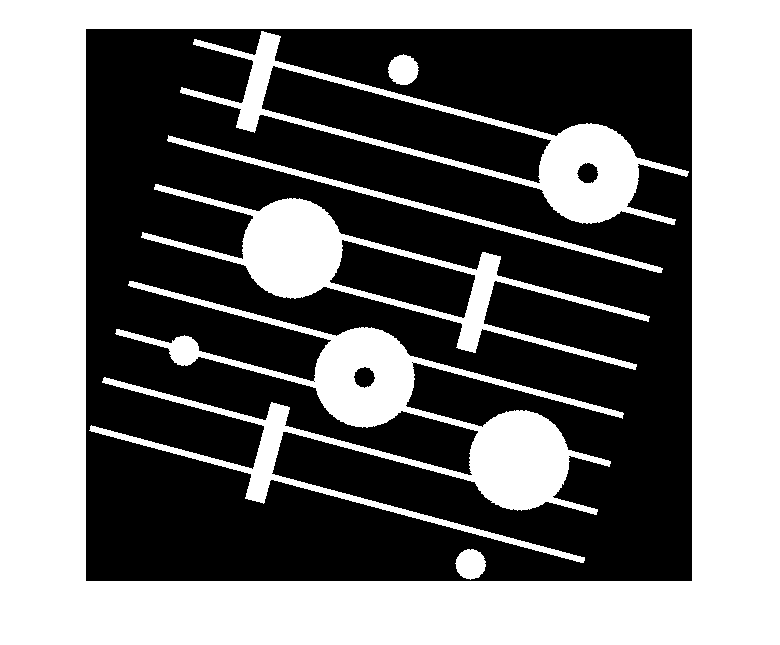

clear
clf
Image1b = imread('Image1b.tif');
imshow(Image1b)

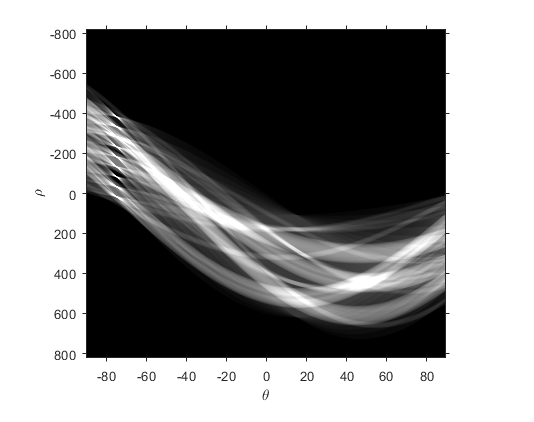


[H, teta, ro] = hough(Image1b, 'Rhoresolution', 5, 'Theta', -90:0.5:89.5);
H1 = imadjust(rescale(H));
imshow(H1,'XData',teta,'YData',ro);
xlabel('\theta'), ylabel('\rho');
axis on, axis normal, hold on;

[r,t] = find(H==max(H(:)));
tetaAngle= 90 + teta(t(1))

tetaAngle = 15

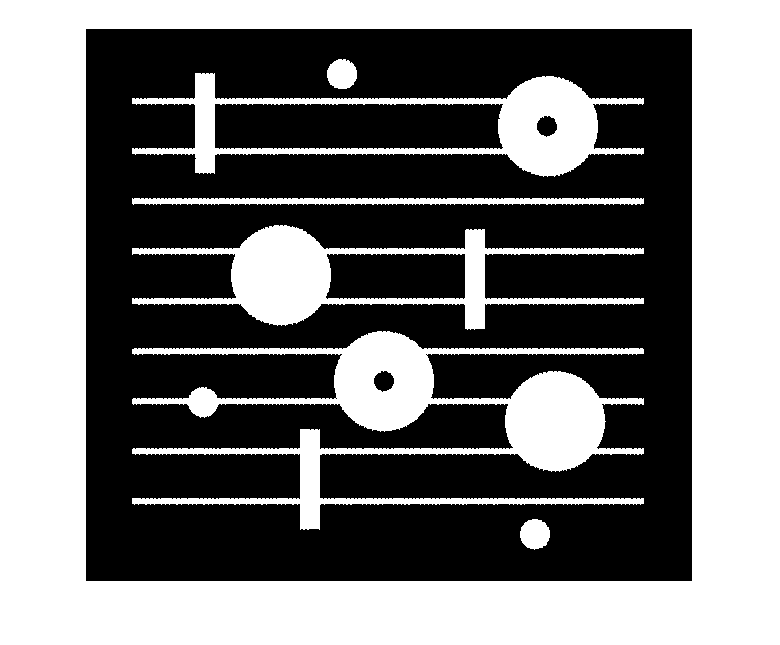

image1b_rotated = imrotate(Image1b,tetaAngle,'bicubic','crop');
clf
figure(2)
imshow(image1b_rotated)

Morphology

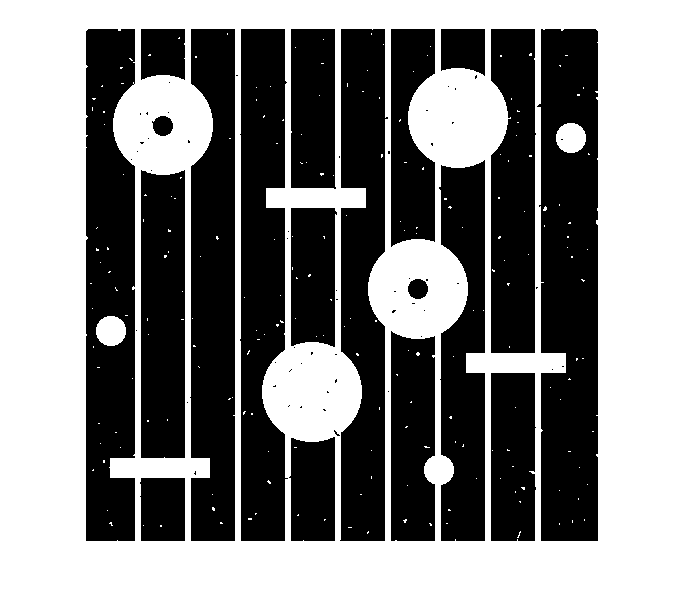

clear
clf
Image1c = imread('Image1c.tif');
imshow(Image1c);

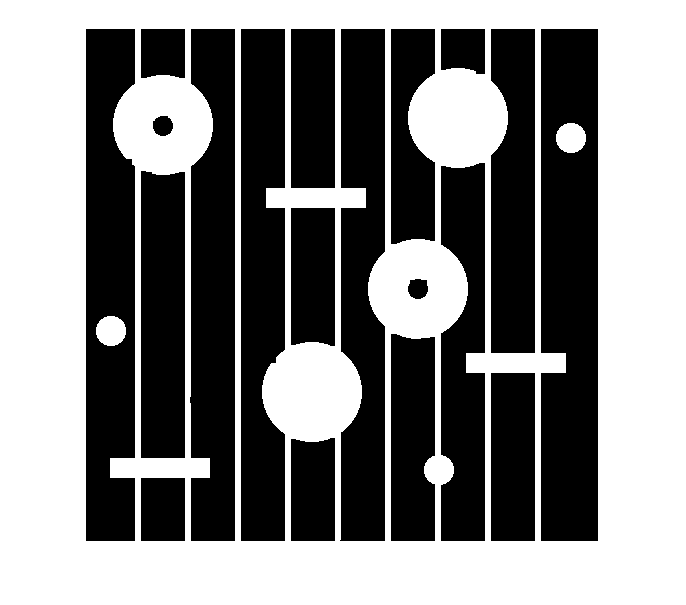


r = 3;
SE = strel('disk',r);
temp = imopen(Image1c, SE);
IM = imclose(temp, SE);
imshow(IM)

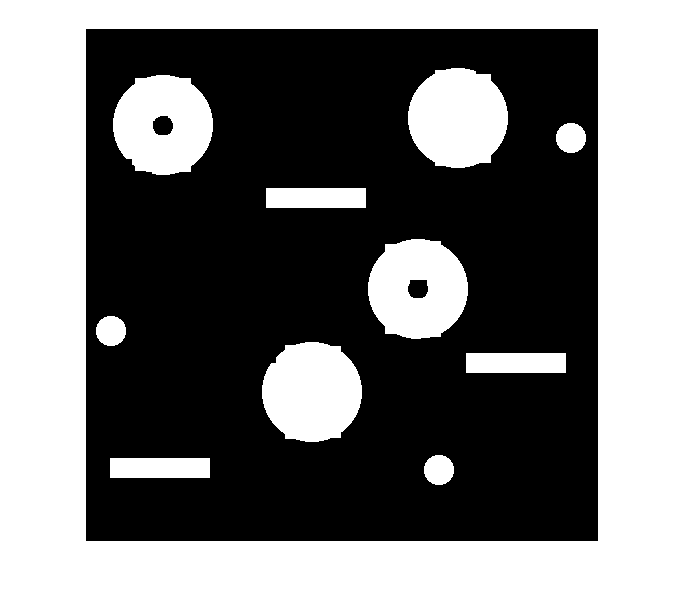

SE = strel('line',6,0);
temp2 = imopen(IM, SE);
Image1c_clean = imclose(temp2, SE);
imshow(Image1c_clean)

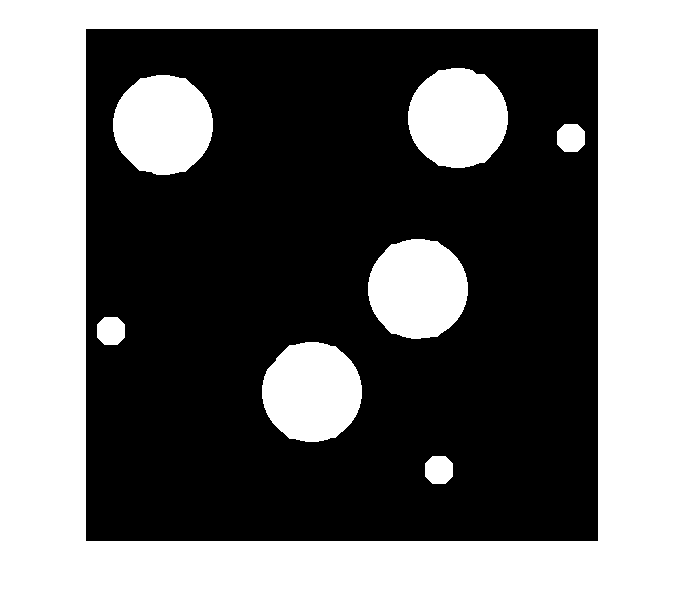

SE = strel('disk',11);
temp2 = imopen(Image1c_clean, SE);
Image1c_clean2 = imclose(temp2, SE);
imshow(Image1c_clean2)

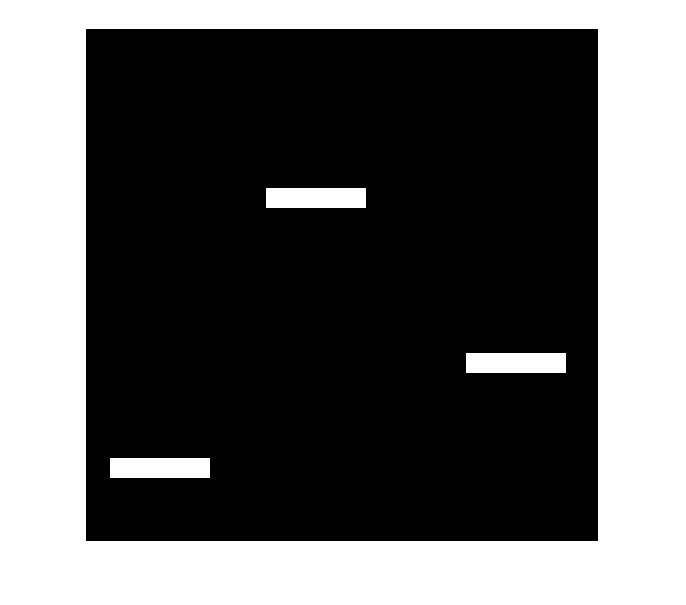

SE = strel('rectangle',[20,100]);
temp2 = imopen(Image1c_clean, SE);
Image1c_Rect = imclose(temp2, SE);
imshow(Image1c_Rect)

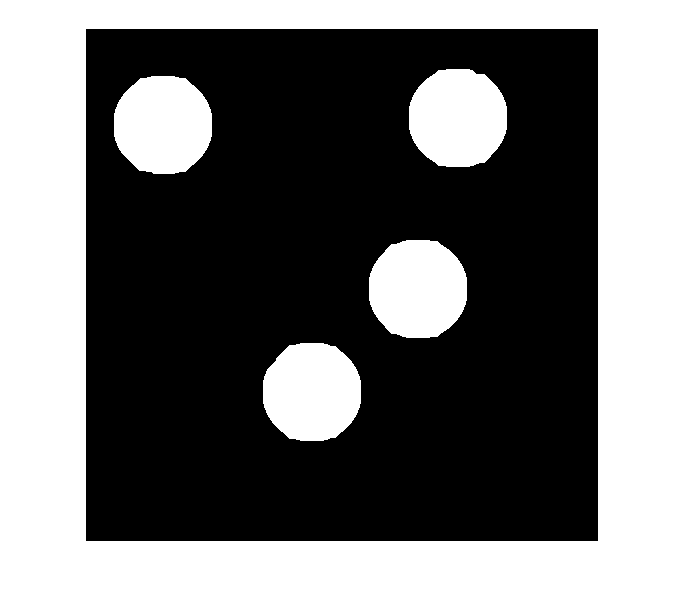

SE = strel('disk',14);
temp2 = imopen(Image1c_clean2, SE);
Image1c_Disk = imclose(temp2, SE);
imshow(Image1c_Disk)

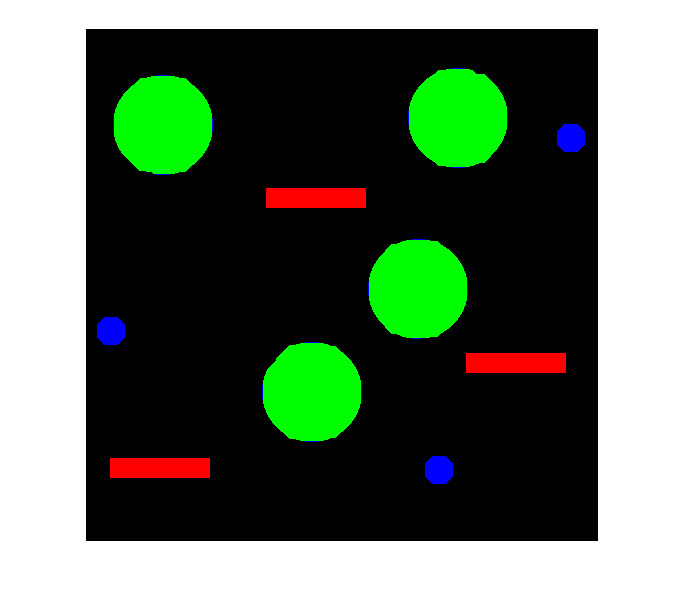

[r,c]=size(Image1c);
RGB=zeros(r,c,3);
RGB(:,:,1)=Image1c_Rect;
RGB(:,:,2)=Image1c_Disk;
RGB(:,:,3)=Image1c_clean2-Image1c_Disk;
imshow(RGB)

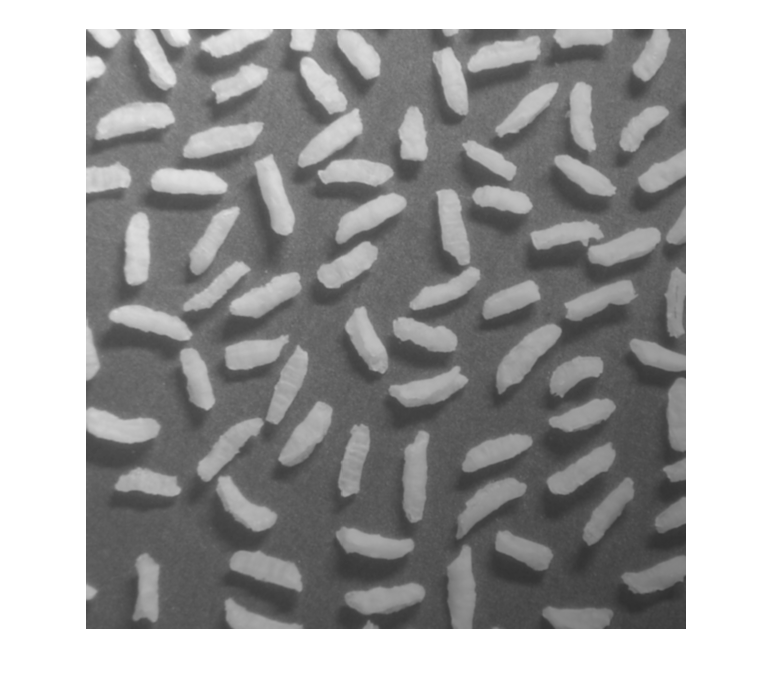

riceshaded = imread('rice-shaded.tif');
imshow(riceshaded)

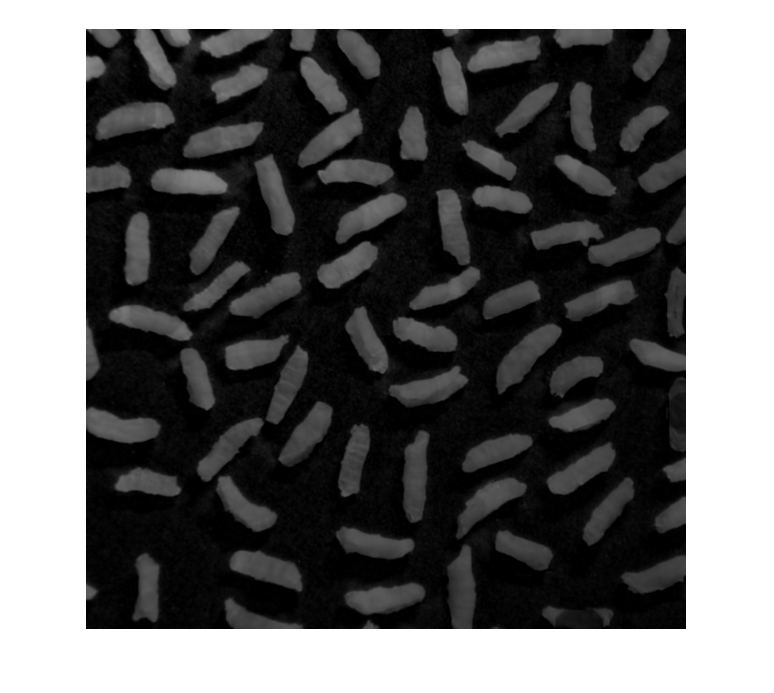

se = strel('disk',18);
tophatFiltered = imtophat(riceshaded,se);
imshow(tophatFiltered)

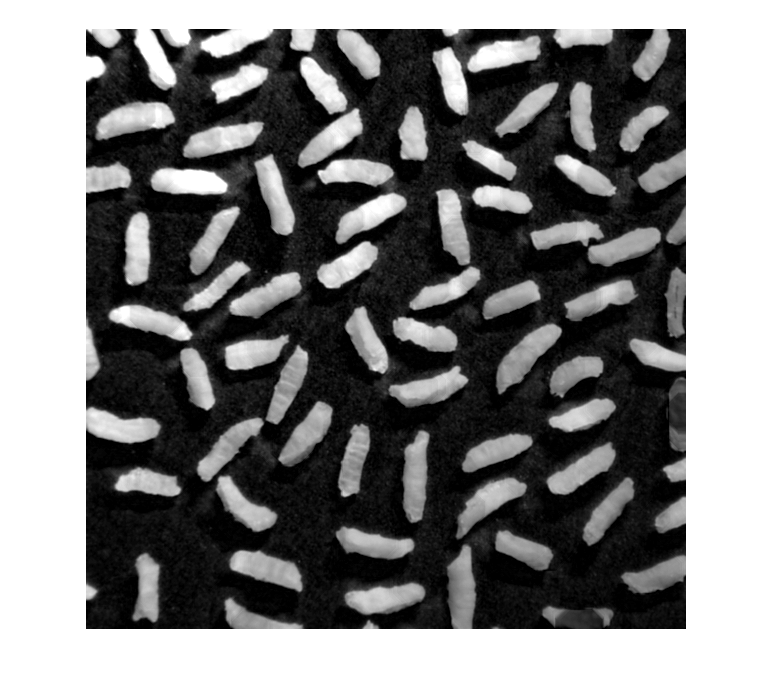

contrastAdjusted = imadjust(tophatFiltered);
imshow(contrastAdjusted)

Labelling and object features

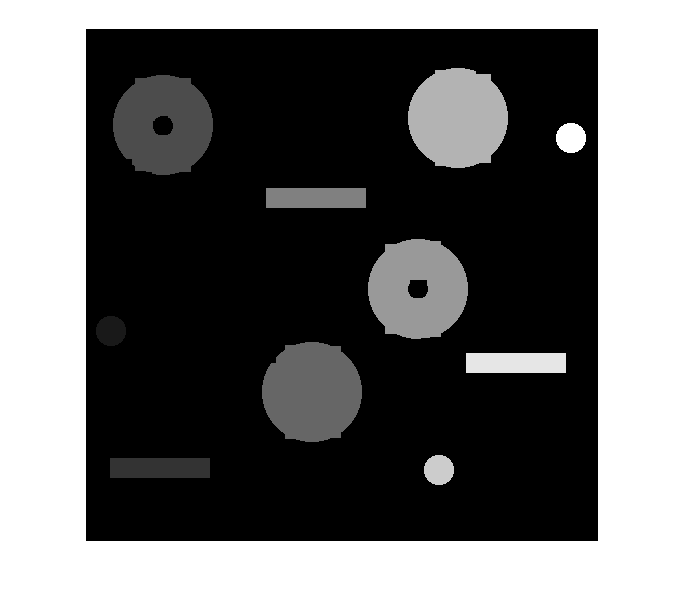

L = bwlabel(Image1c_clean);
imshow(L,[])

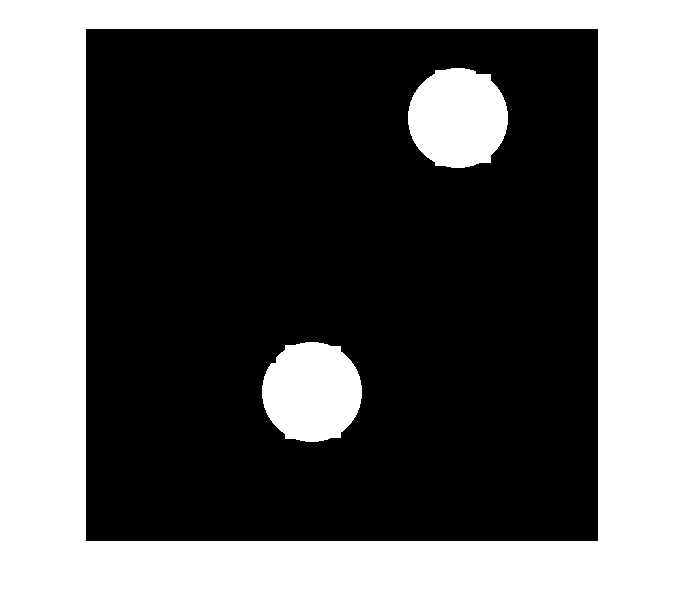

S = regionprops(L,'Perimeter','Area','EulerNumber');
for n=1:length(S)
 Perimeter(n)=S(n).Perimeter;
 Area(n)=S(n).Area;
 Euler(n)=S(n).EulerNumber;
end

LargeO=find(Area>7900);

LargeO_Im=zeros(r,c); % creates an empty matrix
for n=1:length(LargeO) % the number of large objects
 LargeO_Im(L==LargeO(n))=1; % Large object area is set to 1
end
imshow(LargeO_Im)

%hist(Perimeter);